vol7T=medicalVolume("T1_7T_2020")

vol7T =   medicalVolume with properties:

                 Voxels: [128×128×96 int16]
         VolumeGeometry: [1×1 medicalref3d]
           SpatialUnits: "mm"
            Orientation: "sagittal"
           VoxelSpacing: [2 2 2]
           NormalVector: [-1 0 0]
       NumCoronalSlices: 128
      NumSagittalSlices: 96
    NumTransverseSlices: 128
           PlaneMapping: ["coronal"    "transverse"    "sagittal"]
               Modality: "MR"
          WindowCenters: [96×1 double]
           WindowWidths: [96×1 double]


vol3T=medicalVolume("T1_3T_2018")

vol3T =   medicalVolume with properties:

                 Voxels: [192×192×128 int16]
         VolumeGeometry: [1×1 medicalref3d]
           SpatialUnits: "mm"
            Orientation: "coronal"
           VoxelSpacing: [2.6042 2.6042 3.1000]
           NormalVector: [0 1 0]
       NumCoronalSlices: 128
      NumSagittalSlices: 192
    NumTransverseSlices: 192
           PlaneMapping: ["sagittal"    "transverse"    "coronal"]
               Modality: "MR"
          WindowCenters: [128×1 double]
           WindowWidths: [128×1 double]


orthosliceViewer(vol3T)
orthosliceViewer(vol7T)
resample3T=resample(vol3T,vol7T.VolumeGeometry)

resample3T =   medicalVolume with properties:

                 Voxels: [128×128×96 int16]
         VolumeGeometry: [1×1 medicalref3d]
           SpatialUnits: "unknown"
            Orientation: "sagittal"
           VoxelSpacing: [2 2 2]
           NormalVector: [-1 0 0]
       NumCoronalSlices: 128
      NumSagittalSlices: 96
    NumTransverseSlices: 128
           PlaneMapping: ["coronal"    "transverse"    "sagittal"]
               Modality: "unknown"
          WindowCenters: []
           WindowWidths: []


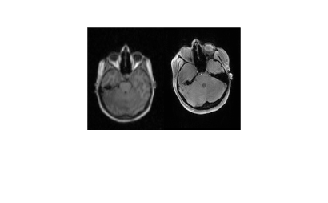

img1=extractSlice(resample3T,64,"transverse");
img2=extractSlice(vol7T,64,"transverse");
imshowpair(img1,img2,'montage')

[optimizer,metric]=imregconfig('multimodal')

optimizer =   registration.optimizer.OnePlusOneEvolutionary

  Properties:
         GrowthFactor: 1.050000e+00
              Epsilon: 1.500000e-06
        InitialRadius: 6.250000e-03
    MaximumIterations: 100

metric =   registration.metric.MattesMutualInformation

  Properties:
    NumberOfSpatialSamples: 500
     NumberOfHistogramBins: 50
              UseAllPixels: 1

newVolxels=imregister(vol7T.Voxels,resample3T.Voxels,'similarity',optimizer,metric)

newVolxels = 128×128×96 int16 array
newVolxels(:,:,1) =

    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0  

registered7T=vol7T

registered7T =   medicalVolume with properties:

                 Voxels: [128×128×96 int16]
         VolumeGeometry: [1×1 medicalref3d]
           SpatialUnits: "mm"
            Orientation: "sagittal"
           VoxelSpacing: [2 2 2]
           NormalVector: [-1 0 0]
       NumCoronalSlices: 128
      NumSagittalSlices: 96
    NumTransverseSlices: 128
           PlaneMapping: ["coronal"    "transverse"    "sagittal"]
               Modality: "MR"
          WindowCenters: [96×1 double]
           WindowWidths: [96×1 double]


registered7T.Voxels=newVolxels;

